%% Partial reproduction by infected individuals
clear

f = 3;
uJ = 0.5;
mo = 2.5;
beta = 0.0;
a = 0; 
uA = 0.5;
mb = 0.2;
fI = 1; %1.5;  %%  0.805 < fI < 1.195 with uA = 0.5

%% S, S1 and S2 bring in different simulations used to get the long-term dynamics

S = load('FIG3_Rcolumn_sim')

S = struct with fields:
          A_I: [404×1 double]
          A_S: [404×1 double]
    AveN_hold: [404×1 double]
            J: [404×1 double]
          Tot: [404×1 double]
    beta_hold: [404×1 double]
     beta_min: 0.1872


S1 = load('FIG3_Rcolumn_sim1')

S1 = struct with fields:
             A_I: [404×1 double]
             A_S: [404×1 double]
           A_sum: [404×1 double]
      AveAI_hold: [404×1 double]
      AveAS_hold: [404×1 double]
    AveAsum_hold: [404×1 double]
       AveJ_hold: [404×1 double]
       AveN_hold: [404×1 double]
               J: [404×1 double]
             Tot: [404×1 double]
       beta_hold: [404×1 double]
        beta_min: 0.1872


S2 = load('FIG3_Rcolumn_sim2')

S2 = struct with fields:
             A_I: [404×1 double]
             A_S: [404×1 double]
           A_sum: [404×1 double]
      AveAI_hold: [404×1 double]
      AveAS_hold: [404×1 double]
    AveAsum_hold: [404×1 double]
       AveJ_hold: [404×1 double]
       AveN_hold: [404×1 double]
               J: [404×1 double]
             Tot: [404×1 double]
       beta_hold: [404×1 double]
        beta_min: 0.1872


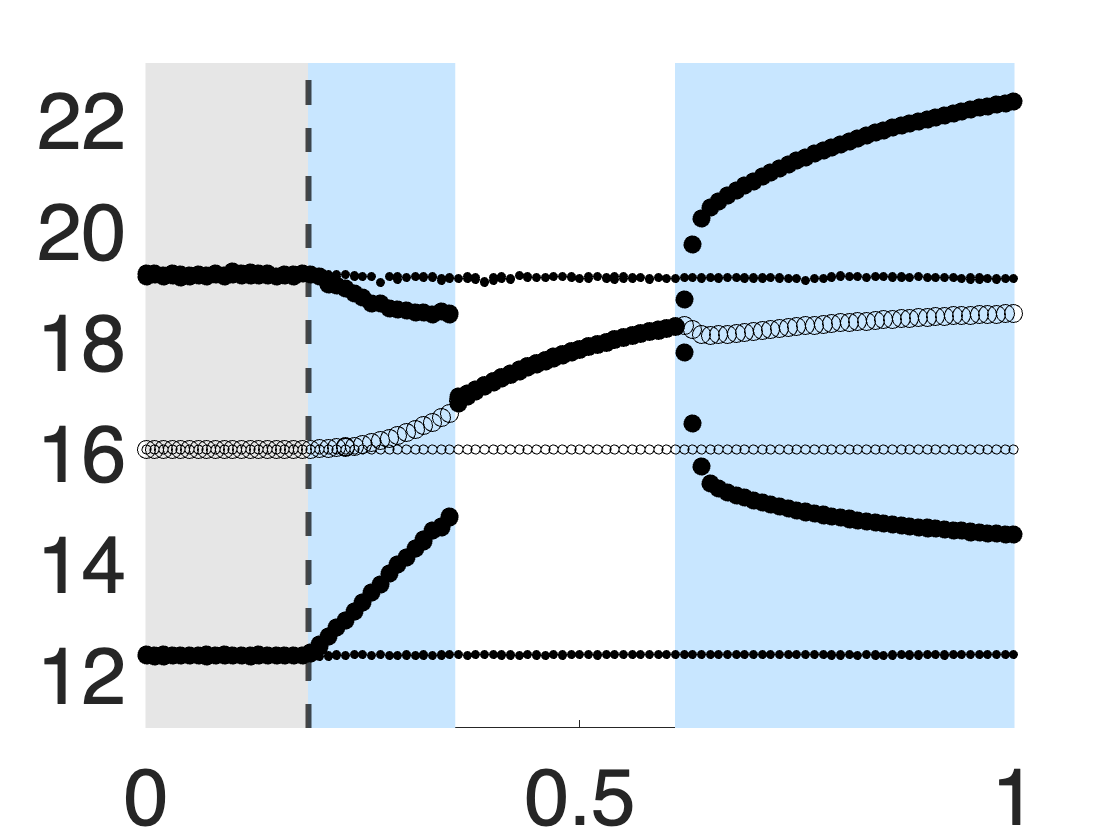


beta_hold_length = length(S1.beta_hold);
beta_hold1 = S1.beta_hold(1:beta_hold_length/4);
beta_hold2 = S1.beta_hold(beta_hold_length/4+1:beta_hold_length/2);
AveN_hold1 = S1.AveN_hold(1:beta_hold_length/4);
AveN_hold2 = S1.AveN_hold(beta_hold_length/4+1:beta_hold_length/2);
Tot1 = S1.Tot(1:beta_hold_length/4);
Tot2 = S1.Tot(beta_hold_length/4+1:beta_hold_length/2);

beta_bound1 = 0.3556; %%Got this from eigenanalysis with Mathematica; saved in Excel%%min(beta_hold1(round(AveN_hold1,3)==round(Tot1,3)));
beta_bound2 = max(beta_hold2(round(AveN_hold2,3)==round(Tot2,3)));


v1 = 1:length(S1.beta_hold)/2;
v2 = length(S1.beta_hold)/2+1:length(S1.beta_hold);
beta1 = S1.beta_hold(v1);
beta2 = S1.beta_hold(v2);

E = S2.beta_hold > S1.beta_min;

%% Figure 3E
figure
colors = get(gca,'ColorOrder');
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound1-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
rectangle('Position',[beta_bound2 0 1-beta_bound2 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
xline(S.beta_min,'--k','LineWidth',3)
scatter(S.beta_hold, S.Tot, 80,"Filled","black")
scatter(S.beta_hold, S.AveN_hold, 80, "black")
scatter(S2.beta_hold, S2.AveN_hold, 20, "black")
scatter(S2.beta_hold, S2.Tot, 20, "black", "filled")
%ylabel("Total")
ylim([11 23])
set(gca, 'FontSize', 40)
%xlabel("Transmission rate, \beta_A", "FontSize", 36)
hold off

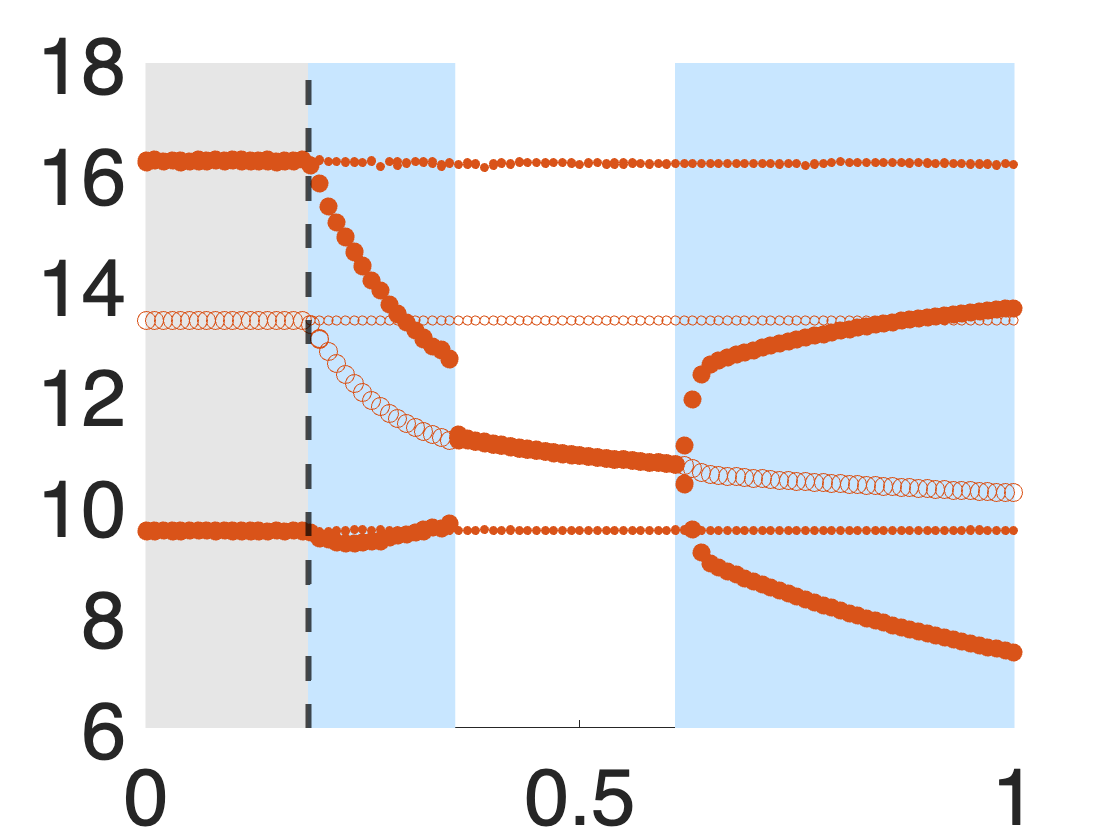



%% Figure 3F
figure
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound1-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
rectangle('Position',[beta_bound2 0 1-beta_bound2 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.J, 80, colors(2,:), "Filled")
scatter(S1.beta_hold, S1.AveJ_hold, 80, colors(2,:))
scatter(S2.beta_hold(E), S2.J(E), 20, colors(2,:), "filled")
scatter(S2.beta_hold(E), S2.AveJ_hold(E), 20, colors(2,:))
%ylabel("J       ")
ylim([6 18])
set(gca, 'FontSize', 40)
%hYLabel = get(gca,'YLabel');
%xlabel("Transmission rate, \beta", "FontSize", 36)
hold off

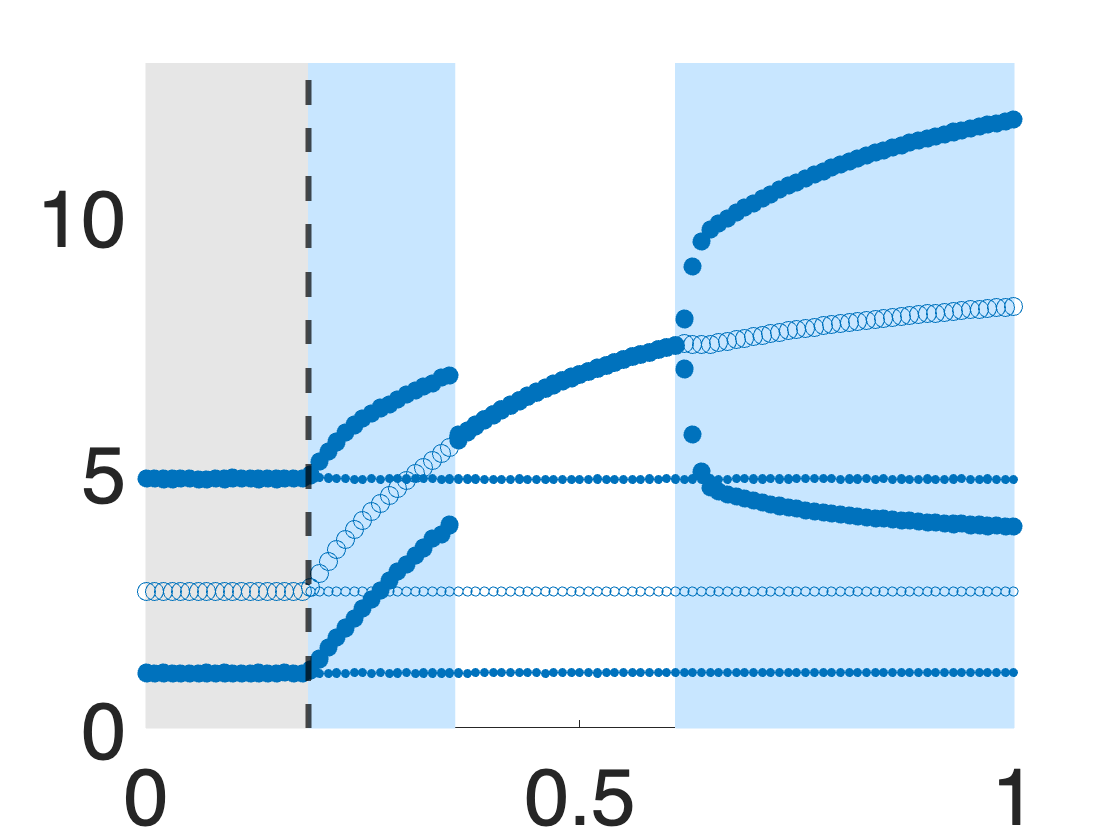



%% Figure 3G
figure 
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound1-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
rectangle('Position',[beta_bound2 0 1-beta_bound2 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.A_sum, 80, colors(1,:), "filled")
scatter(S1.beta_hold, S1.AveAsum_hold, 80, colors(1,:))
scatter(S2.beta_hold(E), S2.A_sum(E), 20, colors(1,:), "filled")
scatter(S2.beta_hold(E), S2.AveAsum_hold(E), 20, colors(1,:))
%ylabel("J       ")
ylim([0 13])
set(gca, 'FontSize', 40)
hold off

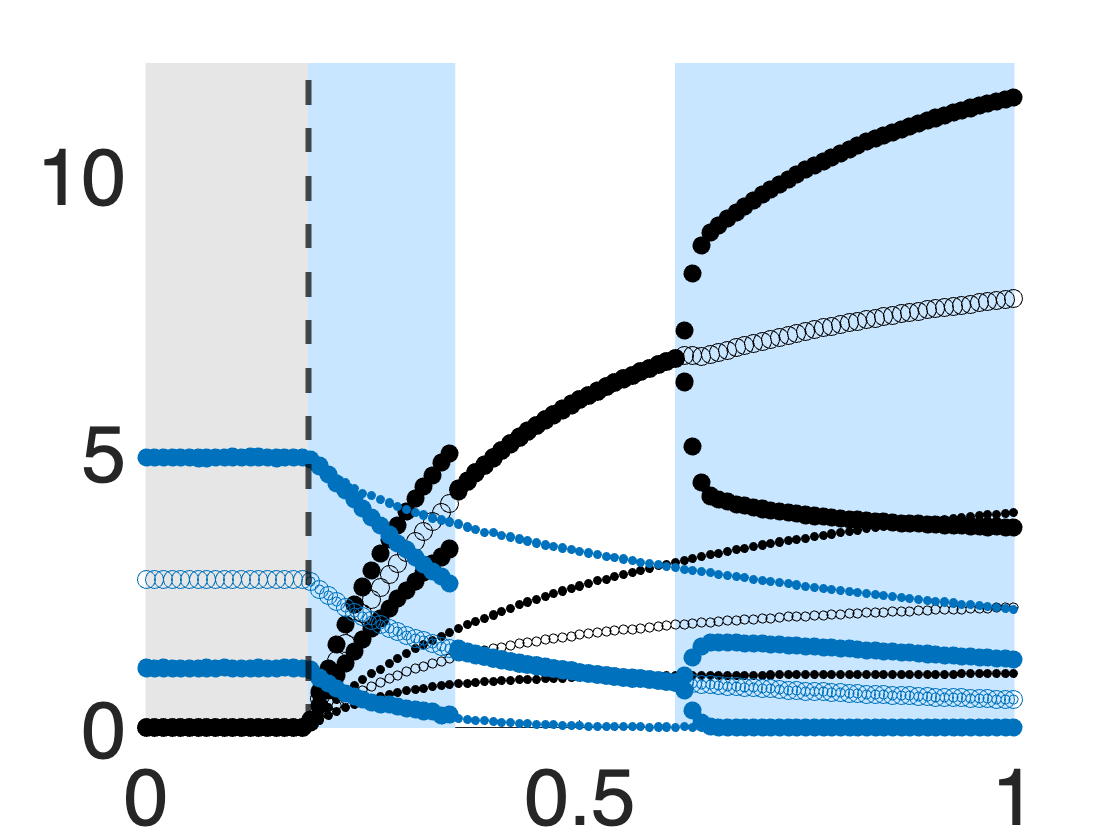



%% Figure 3H
figure
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound1-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
rectangle('Position',[beta_bound2 0 1-beta_bound2 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.A_I, 80, "k", "Filled")
scatter(S1.beta_hold, S1.AveAI_hold, 80, "k")
scatter(S2.beta_hold(E), S2.A_I(E), 20, "k", "filled")
scatter(S2.beta_hold(E), S2.AveAI_hold(E), 20, "k")
scatter(S1.beta_hold, S1.A_S, 80, colors(1,:), "Filled")
scatter(S1.beta_hold, S1.AveAS_hold, 80, colors(1,:))
scatter(S2.beta_hold(E), S2.A_S(E), 20, colors(1,:), "filled")
scatter(S2.beta_hold(E), S2.AveAS_hold(E), 20, colors(1,:))
%xlabel("\beta")
%ylabel("AS       ")
ylim([-0.01 12])
set(gca, 'FontSize', 40)
hYLabel = get(gca,'YLabel');
hold off